# ***Alpha forecasting in factor investing: discriminating between the informational content of the firm characteristics ***

clear;
clc;
warning('off','all');

#### **Data Recovery :**

%Data recovery from our xlsx files.

data1 = readtable('sxxp_zscores.xlsx','VariableNamingRule',"preserve");
data2 = readtable('sxxp_factors_winsorized.xlsx','VariableNamingRule',"preserve");
data3 = readtable('Data_STX.xlsx','Sheet','Rates','VariableNamingRule',"preserve");

% We keep our data into second variables to avoid modifications on the
% original data variables

data_z = data1;
data_f = data2;
data_r = data3(8:end,:);

## **Part II: Alpha forecasting**

In the this part, we compute with two different methods our forecasted alphas :

GK method :


$$\alpha_{\textrm{GK},i,t} =\sigma_{R_t^* } \;k\;C^{-1} z_{i,t-1}$$


with $k=\left(\textrm{Corr}\left\lbrack R_t^* ,g_{1,t-1} \right\rbrack ,\ldotp \ldotp \left\lbrack \textrm{Corr}\left\lbrack R_t^* ,g_{M,t-1} \right\rbrack \right\rbrack \right)$

        
$$z_{i,t-1} =\left(\underset{\overset{\ldotp }{\frac{\left(g_{i,M,t-1} -E\left\lbrack g_{M,t-1} \right\rbrack \right)}{\sigma_{g_{M,t-1} } }} }{\underset{\ldotp }{\ldotp^{\frac{\left(g_{i,1,t-1} -E\left\lbrack g_{1,t-1} \right\rbrack \right)}{\sigma_{g_{1,t-1} } }} } } \right)$$


        
$$C=\textrm{Corr}\left(\left\lbrack g_{1,t-t} \;\ldotp \ldotp \ldotp g_{M,t-t} \right\rbrack \right)$$


Naïve (NZ) method :


$$\alpha_{\textrm{NZ},i,t} ={\sum_{m=1}^M \frac{1}{M}\;\;\frac{\left(g_{i,m,t-1} -E\left\lbrack g_{m,t-1} \right\rbrack \right)}{\sigma_{g_{m,t-1} } }}$$


Building of our main working variables :

% Variables labeling our 3 main dimensions
date = unique(data_z(1:end,1));
firm = unique(data_z(:,2));
characteristics_name = data_z(:,9:end-1).Properties.VariableNames;

% Variables measuring our 3 main dimensions
taille = height(firm);
fin = height(date);
factor = 14;

Computing our data into 2 or 3 dimensions double

tickers_id = findgroups(data_z(:,2));
date_id = findgroups(data_z(:,1));
factor_id = [{'Multifactor'},{'Growth'},{'Value'},{'Quality'},{'Momentum'};{1:14},{1:5},{6:9},{10:12},{13:14}];

%Recovery of monthly return, signals windsorised, z_scores and market_cap
rdt = NaN(fin,taille);
z_scores = NaN(taille, factor,fin);
signals = NaN(taille, factor,fin);
mkt_cap = NaN(fin,taille);

for j=1:taille
    rdt(:,j) = table2array(data_z(tickers_id==j,3));
    z_scores(j,:,:) = table2array(data_z(tickers_id==j,9:22))';
    signals(j,:,:) = table2array(data_f(tickers_id==j,9:22))';
    mkt_cap(:,j) = table2array(data_f(tickers_id==j,8));
end

% Recovery and annualization of risk-less interest rate
rates =  (1 +table2array(data_r(:,2))./100) .^(1/12) -1;

Computation of IC, C, alpha_gk and alpha_nz

[alpha_nz] = forecast_alpha_nz(z_scores);
[alpha_gk,IC,C] = forecast_alpha_gk(rdt,signals,z_scores,rates);

In order to compute the performance of such portfolios, we compute the according weights over time as the following formula :

$a_{\textrm{long}} =\frac{\max \left(\alpha^ˆ ,0\right)}{1^{\prime } \;\max \left(\alpha^ˆ ,0\right)}$ and $a_{\textrm{short}} =\frac{\max \left(-\alpha^ˆ ,0\right)}{1^{\prime } \;\max \left(-\alpha^ˆ ,0\right)}$

Therefore : $a_{\textrm{long}/\textrm{short}\;} =a_{\textrm{long}} -$ $a_{\textrm{short}}$

% Weights computation

[a_long_gk,a_long_short_gk] = weight_calculation(alpha_gk);
[a_long_nz,a_long_short_nz] = weight_calculation(alpha_nz);


Computation of the portfolios : L/S GK, Long GK, L/S NZ, Long NZ, Benchmark ("S&P"), EquallyWeighted

% Return Computation
gap=1;

rdt_long_short_gk = return_calculation(rdt,a_long_short_gk,gap);
rdt_long_gk = return_calculation(rdt,a_long_gk,gap);
rdt_long_short_nz = return_calculation(rdt,a_long_short_nz,gap);
rdt_long_nz = return_calculation(rdt,a_long_nz,gap);
rdt_snp = return_calculation(rdt,(mkt_cap./sum(mkt_cap,2,'omitnan'))',gap);
rdt_equally_w = mean(rdt,2,'omitnan')';

Plot of our stocks universe

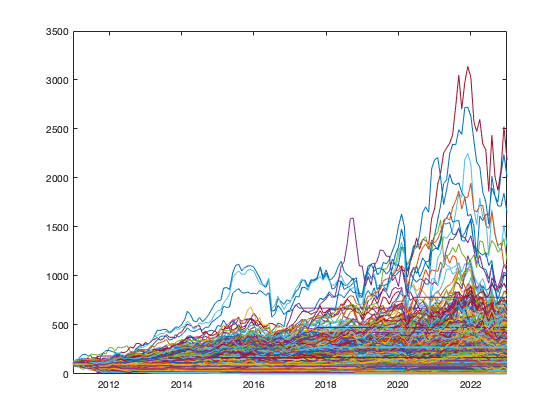

figure;
plot(table2array(date),100*cumprod(1+rdt,1,'omitnan'));

Plot of our portfolios

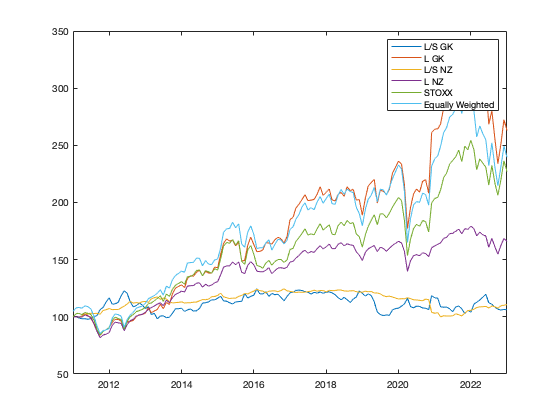

debut=1;
arret=fin;

plot(table2array(date(debut:arret,1)),100*cumprod(1+rdt_long_short_gk(1,debut:arret)));
hold on
plot(table2array(date(debut:arret,1)),100*cumprod(1+rdt_long_gk(1,debut:arret)));
hold on
plot(table2array(date(debut:arret,1)),100*cumprod(1+rdt_long_short_nz(1,debut:arret)));
hold on
plot(table2array(date(debut:arret,1)),100*cumprod(1+rdt_long_nz(1,debut:arret)));
hold on
plot(table2array(date(debut:arret,1)),100*cumprod(1+rdt_snp(1,debut:arret)));
hold on
plot(table2array(date(debut:arret,1)),100*cumprod(1+rdt_equally_w(1,debut:arret)));
legend(["L/S GK", "L GK", "L/S NZ", "L NZ", "STOXX", "Equally Weighted"]);

This is with the types of alpha forecasting calculation that we are going to simalate and back-test our data.

## **Part IV: Simulation**

In this part, we are going to simulate a universe of stocks and z_scores. Then, we will estimate IC as well as its influence on the performance of our portfolios.

#### A - Simulation of the model universe

The function simulation.m takes into input :

- Benchmark return observations 

- Stock universe returns

- IC observations

- C matrix of observes z_scores correlations

- Sizes of our dimensions

The function simulates within a mutifactor model as follows :


$$R_{i,t}^* =\alpha_{i,t} +\beta_i R_{B,t}^* +\varepsilon_{i,t}$$


where 

            $\alpha_{i,t} =\sigma_{\sigma_{i,t} } {\;k}_{\textrm{CS},t} {\;C}_{\textrm{CS},t}^{-1} \;z_{i,t-1}$ with $z_{i,t-1} \sim N\left(0,C_{\textrm{CS}} \right)$

            
$$\varepsilon_t \sim N\left(0,\psi \right)$$
 

            and $R_{B,t}^*$$\sim N\left(\mu_B ,\sigma_B \right)$

% Calculation of one simualation sample of a universe
[rdt_simul,alpha_simul,beta,rdt_bench,epsilon,z_simul,theta] = simulation(rdt_snp,rdt,IC,C,taille,factor,fin);

  The function output are :

- Simulated stocks returns

- Alpha simulated used in the multifactor model

- Beta simulated used in the multifactor model

- Simulated benchmark returns

- Espilon used in the multifactor model

- Simulated z_scores following some assumptions

Plot of the stock returns univers and its benchmark

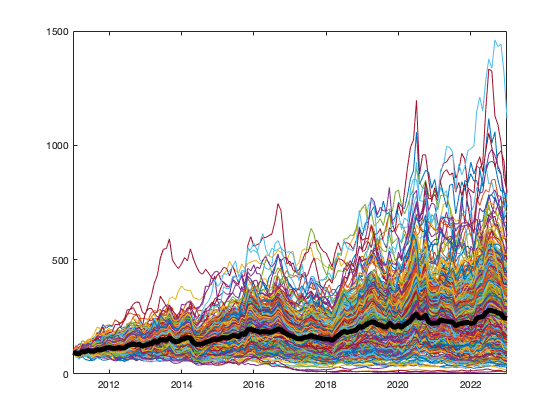

figure;
plot(table2array(date(:,1)),100*cumprod(1+rdt_simul,1,'omitnan'));
hold on
plot(table2array(date(:,1)),100*cumprod(1+rdt_bench,'omitnan'),'LineWidth',5, 'Color','k');

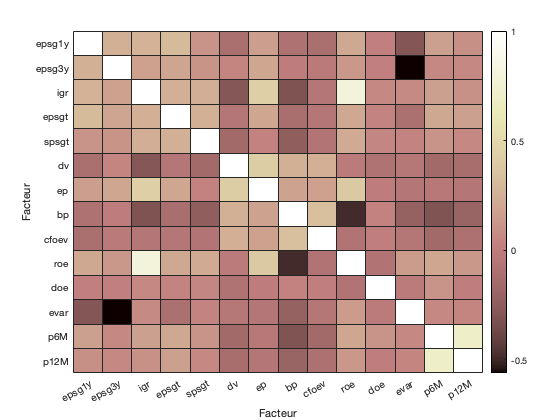

% Average simulated z_scores simulation
figure;
h= heatmap(corr(nanmean(z_simul,3),'rows','complete'));
xlabel('Facteur');
ylabel('Facteur');
h.YDisplayLabels = ["epsg1y","epsg3y","igr","epsgt","spsgt","dv","ep","bp","cfoev","roe","doe","evar","p6M","p12M"];
h.XDisplayLabels = ["epsg1y","epsg3y","igr","epsgt","spsgt","dv","ep","bp","cfoev","roe","doe","evar","p6M","p12M"];
h.CellLabelFormat = '%0.2g ';
h.Colormap = pink;

#### B - Portfolio construction

Within our simulated universe, we are going to compute alpha_gk and alpha_nz estimates and weight our portfolio with them. 

The estimates are computed on a rolling period of 60 months as follows :

- 
$${\alpha^ˆ }_{\textrm{GK},i,t} ={\hat{k} } \;{\hat{\underset{}{C^{-1} \;}} \;z_{i,t-1} }$$


            with $\hat{k} =\left(\hat{{\textrm{IC}}_1 } \;\ldotp \ldotp \ldotp \hat{{\textrm{IC}}_M } \right)$ and $\hat{{\textrm{IC}}_m } =\frac{1}{59}\sum_{t=1}^{59} \textrm{Corr}\left\lbrack \theta_t \;,z_{m,t-1} \right\rbrack$

            and $\hat{C} =\frac{1}{60}\sum_{t=1}^{60} {\overset{}{C} }_t$

- ${\alpha^ˆ }_{\textrm{NZ},i,t}$= $\sum_{m=1}^M z_{i,m,t-1}$

The function weights_computing takes in input the simulated stock returns, benchmark return and z_scores.

Its output are the weight in long and short for the GK and NZ strategies (Multifactor, Growth, Value, Quality and Momentum).

% Computation of the GK and NZ portfolio weights
rolling = 60;

alpha_simul_gk = zeros(fin-rolling,taille,size(factor_id,2));
alpha_simul_nz = zeros(fin-rolling,taille,size(factor_id,2));

a_simul_long_gk = zeros(taille,fin-rolling,size(factor_id,2));
a_simul_ls_gk = zeros(taille,fin-rolling,size(factor_id,2));
a_simul_long_nz = zeros(taille,fin-rolling,size(factor_id,2));
a_simul_ls_nz = zeros(taille,fin-rolling,size(factor_id,2));

%for each strategy
for i=1:size(factor_id,2)    
    [alpha_simul_gk(:,:,i),~] = estimate_calculation(rdt_simul,rdt_bench, z_simul(:,factor_id{2,i},:), rolling);
    alpha_simul_nz(:,:,i) = squeeze(sum(z_simul(:,factor_id{2,i},rolling+1:end),2))';
    
    [a_simul_long_gk(:,:,i),a_simul_ls_gk(:,:,i)] = weight_calculation(alpha_simul_gk(:,:,i));
    [a_simul_long_nz(:,:,i),a_simul_ls_nz(:,:,i)] = weight_calculation(alpha_simul_nz(:,:,i));
end

Computation of the performance of the GK, NZ multifactor strategy and equally weighted strategy

gap =1;
rdt_simul_gk = return_calculation(rdt_simul(rolling+1:end,:),a_simul_long_gk(:,:,1),gap);
rdt_simul_nz = return_calculation(rdt_simul(rolling+1:end,:),a_simul_long_nz(:,:,1),gap);
rdt_simul_equally_weighted = nanmean(rdt_simul(rolling+1:end,:),2)';
rdt_simul_equally_weighted(1,1)=0;

Plot of the performance of the GK, NZ and equally weighted strategy

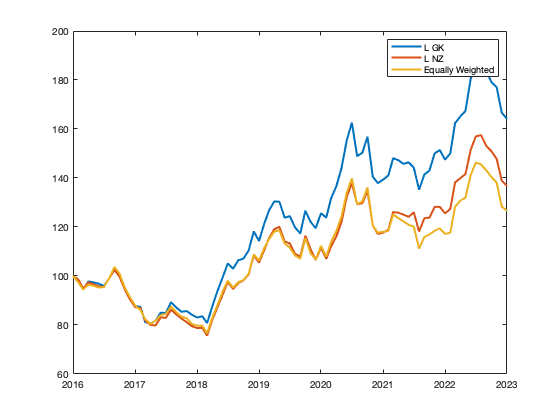

figure;
plot(table2array(date(rolling+1:end,1)),100*cumprod(1+rdt_simul_gk(1,:),'omitnan'),'LineWidth',2);
hold on
plot(table2array(date(rolling+1:end,1)),100*cumprod(1+rdt_simul_nz(1,:),'omitnan'),'LineWidth',2);
hold on 
plot(table2array(date(rolling+1:end,1)),100*cumprod(1+rdt_simul_equally_weighted(1,:),'omitnan'),'LineWidth',2);
legend(["L GK", "L NZ", "Equally Weighted"]);

In order to get a consistent result, we must realize an important number of simulations and estimate our ICs and alphas.

#### C - IC estimates, realized alphas and IR

The IC are estimates with an average across simulation samples with the $\hat{\textrm{IC}} m$ estimator presented above.

The realized alpha $\alpha_{A,\textrm{GK},t}$ and $\alpha_{A,\textrm{NZ},t}$ are computed as follows :

$\alpha_{A,\textrm{GK},t}$ = $a_{A,\textrm{GK},t-1}^{\prime } \alpha_t$ and $\alpha_{A,\textrm{NZ},t}$ = $a_{A,\textrm{NZ},t-1}^{\prime } \alpha_t$

The realized portfolio information ratios ${\textrm{IR}}_{A,\textrm{GK},t\;}$and ${\textrm{IR}}_{A,\textrm{NZ},t\;}$are computed as follows :

${\textrm{IR}}_{A,\textrm{GK},t\;}$= $\frac{\alpha_{A,\textrm{GK},t} }{\sqrt{{a^{\prime } }_{A,\textrm{GK},t-1} \;\psi \;a_{A,\textrm{GK},t-1} }}$ and ${\textrm{IR}}_{A,\textrm{NZ},t\;}$= $\frac{\alpha_{A,\textrm{NZ},t} }{\sqrt{{a^{\prime } }_{A,\textrm{NZ},t-1} \;\psi \;a_{A,\textrm{NZ},t-1} }}$

%Realization of 1000 simulations and weights computation
nb_simul =10;

%What we called true IC are the ICs from our observation
true_IC = IC(rolling+1:fin,:);

IC_estimate = zeros(nb_simul,fin-rolling,factor);

erreur = zeros(nb_simul,factor);
signe = zeros(nb_simul,factor);

alpha_realized_gk = zeros(nb_simul, fin - rolling,size(factor_id,2));
alpha_realized_nz = zeros(nb_simul, fin - rolling,size(factor_id,2));

IR_gk = zeros(nb_simul, fin - rolling,size(factor_id,2));
IR_nz = zeros(nb_simul, fin - rolling,size(factor_id,2));

gap=1;

for i=1:nb_simul
    
    %Simulation of a new universe
    [rdt_simul,alpha_simul,~,rdt_bench,~,z_simul,true_theta] = simulation(rdt_snp,rdt,IC,C,taille,factor,fin);
    
    %Computation of the IC estimates
    [~,IC_estimate(i,:,:)] = estimate_calculation(rdt_simul,rdt_bench,z_simul(:,factor_id{2,1},:), rolling);
    
    %Computation of the GK and NZ, Long and Short portfolio weights for
    %each strategy (Multifactor, Growth, Value, Quality, Momentum)
    for j=1:size(factor_id,2)    
        [alpha_simul_gk(:,:,j),~] = estimate_calculation(rdt_simul,rdt_bench, z_simul(:,factor_id{2,j},:), rolling);
        alpha_simul_nz(:,:,j) = squeeze(sum(z_simul(:,factor_id{2,j},rolling+1:end),2))';
        
        [a_simul_long_gk(:,:,j),a_simul_ls_gk(:,:,j)] = weight_calculation(alpha_simul_gk(:,:,j));
        [a_simul_long_nz(:,:,j),a_simul_ls_nz(:,:,j)] = weight_calculation(alpha_simul_nz(:,:,j));
    end
    
    %Difference between the IC estimate and the true IC
    erreur(i,:) = squeeze(nanmean(IC_estimate(i,:,:),2)) - mean(true_IC,1)';
    
    %Variable with positive coefficients if the IC estimates and the true
    %IC have the same sign and inversly with negative coefficients if the
    %IC estimates and true IC have opposite sign
    signe(i,:) = squeeze(nanmean(IC_estimate(i,:,:),2)).*mean(true_IC,1)';
    
    % for each strategy (Multifactor, Growth, Value, Quality, Momentum)
    for j=1:size(factor_id,2)
        
        [alpha_realized_gk(i,:,j)] = realized_alpha_calculation(alpha_simul(rolling+1:end,:),a_simul_ls_gk(:,:,j),gap)*12;
        [alpha_realized_nz(i,:,j)] = realized_alpha_calculation(alpha_simul(rolling+1:end,:),a_simul_ls_nz(:,:,j),gap)*12;
        
        [IR_gk(i,:,j)] = ir_calculation(alpha_realized_gk(i,:,j),a_simul_ls_gk(:,:,j), true_theta,1);
        [IR_nz(i,:,j)] = ir_calculation(alpha_realized_nz(i,:,j),a_simul_ls_nz(:,:,j), true_theta,1);
        
    end
end

**IC estimates results:**

%IC simulation results from our simulations sample
tableau_IC = table('Size',[factor 7],'VariableType',{'double', 'double','double','double','double','double','double'},'VariableNames',{'true_IC','IC_estimate','Bias','Precision','true_in_per','est_in_per','DHR_in_per'},'RowNames',characteristics_name);
tableau_IC.IC_estimate = round(squeeze(nanmean(nanmean(IC_estimate,1),2)),3);
tableau_IC.Precision = round(sqrt(nanmean(erreur.^2,1)'),3);
tableau_IC.true_IC = round(mean(true_IC,1)',3);
tableau_IC.Bias = round(mean(true_IC,1)',3) - round(squeeze(nanmean(nanmean(IC_estimate,1),2)),3);
tableau_IC.DHR_in_per = round((100*sum(signe>0)/nb_simul)',3);
tableau_IC.est_in_per = round(100*mean(squeeze(sum(IC_estimate>0,1))/nb_simul,1)',1);
tableau_IC.true_in_per = round(100*mean(true_IC>0,1)',1);

disp(tableau_IC)

               true_IC    IC_estimate     Bias     Precision    true_in_per    est_in_per    DHR_in_per
               _______    ___________    ______    _________    ___________    __________    __________

    EPSG1Y     -0.009        0.003       -0.012      0.015         49.4           57.7          36.4   
    EPSG3Y     -0.004       -0.003       -0.001      0.007         44.7             37          67.7   
    IGR         0.013        0.019       -0.006      0.016         54.1           82.1          89.1   
    EPSGT       0.005        0.009       -0.004      0.011         55.3           71.3          77.5   
    SPSGT      -0.001        0.017       -0.018     

**Realized Alpha results:**


%GK Alpha simulation result from our simulations sample
tableau_alpha_gk = table('Size',[5 4],'VariableType',{'double','double','double','double'},'VariableNames',{'Mean','SE','Qt25','Qt75'},'RowNames',factor_id(1,:));
for i=1:size(factor_id,2)
    tableau_alpha_gk.Mean(i) = round(mean(nanmean(alpha_realized_gk(:,:,i)*100,2)),2);
    tableau_alpha_gk.SE(i) = round(std(nanmean(alpha_realized_gk(:,:,i),2)*100),2);
    tableau_alpha_gk.Qt25(i) = round(quantile(nanmean(alpha_realized_gk(:,:,i)*100,2),.025),2);
    tableau_alpha_gk.Qt75(i) = round(quantile(nanmean(alpha_realized_gk(:,:,i),2)*100,.975),2);
end
disp(tableau_alpha_gk);

                   Mean     SE     Qt25     Qt75 
                   ____    ____    _____    _____

    Multifactor    7.85    1.98     4.15    12.09
    Growth         3.85    1.56     0.96      7.2
    Value          4.49    1.77     1.11     8.23
    Quality        3.77    2.03    -0.02     7.95
    Momentum        4.5    2.04     0.61     8.62



%NZ Alpha simulation result from our simulations sample
tableau_alpha_nz = table('Size',[5 4],'VariableType',{'double','double','double','double'},'VariableNames',{'Mean','SE','Qt25','Qt75'},'RowNames',factor_id(1,:));
for i=1:size(factor_id,2)
    tableau_alpha_nz.Mean(i) = round(mean(nanmean(alpha_realized_nz(:,:,i),2))*100,2);
    tableau_alpha_nz.SE(i) = round(std(nanmean(alpha_realized_nz(:,:,i),2))*100,2);
    tableau_alpha_nz.Qt25(i) = round(quantile(nanmean(alpha_realized_nz(:,:,i),2),.025)*100,2);
    tableau_alpha_nz.Qt75(i) = round(quantile(nanmean(alpha_realized_nz(:,:,i),2),.975)*100,2);
end
disp(tableau_alpha_nz);

                   Mean      SE     Qt25     Qt75
                   _____    ____    _____    ____

    Multifactor     2.78    1.86    -0.94    6.38
    Growth          1.54    1.84    -2.06    5.14
    Value          -0.07     2.2    -4.15    4.44
    Quality         2.24    2.65    -2.88    7.36
    Momentum        2.84    2.48    -2.16     7.8



**Information Ratio results :**

%GK realized actual portfolio information ratios result from our simulations sample
tableau_IR_gk = table('Size',[5 4],'VariableType',{'double','double','double','double'},'VariableNames',{'Mean','SE','Qt25','Qt75'},'RowNames',factor_id(1,:));
for i=1:size(factor_id,2)
    tableau_IR_gk.Mean(i) = round(mean(nanmean(IR_gk(:,:,i),2)/sqrt(12)),2);
    tableau_IR_gk.SE(i) = round(std(nanmean(IR_gk(:,:,i),2)/sqrt(12)),2);
    tableau_IR_gk.Qt25(i) = round(quantile(nanmean(IR_gk(:,:,i),2)/sqrt(12),.025),2);
    tableau_IR_gk.Qt75(i) = round(quantile(nanmean(IR_gk(:,:,i),2)/sqrt(12),.975),2);
end
disp(tableau_IR_gk);

                   Mean      SE     Qt25    Qt75 
                   _____    ____    ____    _____

    Multifactor    10.15    2.59    5.39     15.6
    Growth          4.97    2.05    1.01     9.34
    Value           5.83    2.32    1.49    10.68
    Quality         4.86    2.65    -0.2     10.2
    Momentum        5.83    2.64    0.71     11.2



%NZ realized actual portfolio information ratios result from our simulations sample
tableau_IR_nz = table('Size',[5 4],'VariableType',{'double','double','double','double'},'VariableNames',{'Mean','SE','Qt25','Qt75'},'RowNames',factor_id(1,:));
for i=1:size(factor_id,2)
    tableau_IR_nz.Mean(i) = round(mean(nanmean(IR_nz(:,:,i),2)/sqrt(12)),2);
    tableau_IR_nz.SE(i) = round(std(nanmean(IR_nz(:,:,i),2)/sqrt(12)),2);
    tableau_IR_nz.Qt25(i) = round(quantile(nanmean(IR_nz(:,:,i),2)/sqrt(12),.025),2);
    tableau_IR_nz.Qt75(i) = round(quantile(nanmean(IR_nz(:,:,i),2)/sqrt(12),.975),2);
end
disp(tableau_IR_nz);

                   Mean      SE     Qt25     Qt75
                   _____    ____    _____    ____

    Multifactor      3.6    2.41    -1.26    8.25
    Growth          1.98     2.4    -2.74    6.71
    Value          -0.09    2.87    -5.54    5.78
    Quality         2.92    3.45    -3.74     9.5
    Momentum        3.69    3.21    -2.81    9.83



## **Extension n°2 : Simplified simulation extension**

Comparaison between Top-Down approach (TD), Bottom-Up GK approach (BU GK) and Bottom-Up NZ approach (BU NZ) for only two signals in 4 differents stylized exemple.

%We built our 4 stylized exemple parameters
low_IC_ext = [0.03 0.03];
high_IC_ext = [0.03 0.01];
low_C_ext = [1 0.1;0.1 1];
high_C_ext = [1 0.9;0.9 1];

Display of our results

tableau_ext = table('Size',[4 3],'VariableType',{'double','double','double'},'VariableNames',{'TD (%)','NZ BU (%)','GK BU (%)'},'RowNames',{'Low signal corr & low dispertion','Low signal corr & high IC dispertion','High signal corr & low IC dispertion','High signal corr & high IC dispertion' });
% Low corr & low IC scenario
tableau_ext(1,:) = extension_scenario(rdt_snp,rdt,low_IC_ext,low_C_ext,rolling,gap);
% Low corr & high IC scenario
tableau_ext(2,:) = extension_scenario(rdt_snp,rdt,high_IC_ext,low_C_ext,rolling,gap);
% High corr & low IC scenario
tableau_ext(3,:) = extension_scenario(rdt_snp,rdt,low_IC_ext,high_C_ext,rolling,gap);
% High corr & high IC scenario
tableau_ext(4,:) = extension_scenario(rdt_snp,rdt,high_IC_ext,high_C_ext,rolling,gap);

disp(tableau_ext)

                                             TD (%)    NZ BU (%)    GK BU (%)
                                             ______    _________    _________

    Low signal corr & low dispertion         2.7597     3.7167       3.7084  
    Low signal corr & high IC dispertion     1.8651     2.5154       2.8478  
    High signal corr & low IC dispertion       2.85     2.9244       2.8992  
    High signal corr & high IC dispertion    1.8155     1.8622        4.472  

